## Linear Algebra

This notebook includes some exercises to related to linear algebra in MATLAB. Prepared for EAS Practical Coding and Math course at Georgia Tech.

### Vectors and their products

First lets define some vectors

x = [2;9;4;2;-4]

x =      2
     9
     4
     2
    -4


y = [8;5;-4;1;-2]

y =      8
     5
    -4
     1
    -2


Inner product of two vectors is a scalar

x'*y

ans = 55

Cross product of two vectors is another vector (though cross products are only defined for vectors of length 3

cross(x(1:3),y(1:3))

ans =    -56
    40
   -62


The outer product of two vectors is a matrix

x*y'

ans =     16    10    -8     2    -4
    72    45   -36     9   -18
    32    20   -16     4    -8
    16    10    -8     2    -4
   -32   -20    16    -4     8


### Simple Statistics from Vectors

Anomalies from mean

xanom = x-mean(x)

xanom =    -0.6000
    6.4000
    1.4000
   -0.6000
   -6.6000


Variance of vector x

xanom'*xanom / (length(x)-1)

ans = 21.8000

Calculated another way

std(x)^2

ans = 21.8000

Co-variance between two vectors

yanom = y-mean(y)

yanom =     6.4000
    3.4000
   -5.6000
   -0.6000
   -3.6000


xanom'*yanom / (length(x)-1)

ans = 8.5500

### Matrix algebra

Solving various version of the Ax=b problem which solves a linear system of equations

A = [1 -1;1 1]

A =      1    -1
     1     1


b = [0;2]

b =      0
     2


Using inv

xnew = inv(A)*b

xnew =      1
     1


Or using \

xnew = A\b

xnew =      1
     1


### Matrix algebra for underconstrained problems

Solving Ax=b when A is rectangular (more variables than equations)

A = [1 -3 4 5 9;2 6 -3 4 8;-1 0 -8 3 5]

A =      1    -3     4     5     9
     2     6    -3     4     8
    -1     0    -8     3     5


b = [3;5;2]

b =      3
     5
     2


If we try to solve this the normal way, MATLAB will be unhappy

%inv(A)*b

But lets use the psedo-inverse which allows us to solve the least squares problem (i.e. the closest solution matching the constraints)

xnew = pinv(A)*b

xnew =     0.1091
    0.2607
   -0.0033
    0.1560
    0.3229


### Calculating a linear regression with real data

Load in and plot Atlanta monthly mean temperature data

data=load('ATL_MonMeanTemp_1879_2020.mat');
data = data.ATLtemp

data = 1.0e+03 *

    1.8790    0.0443    0.0437    0.0576    0.0589    0.0698    0.0749    0.0796    0.0739    0.0687    0.0643    0.0539    0.0515
    1.8800    0.0543    0.0514    0.0555    0.0634    0.0710    0.0765    0.0792    0.0768    0.0694    0.0608    0.0472    0.0421
    1.8810    0.0401    0.0466    0.0491    0.0591    0.0708    0.0778    0.0811    0.0788    0.0755    0.0672    0.0526    0.0496
    1.8820    0.0488    0.0524    0.0574    0.0648    0.0661    0.0766    0.0759    0.0758    0.0717    0.0658    0.0511    0.0414
    1.8830    0.0430    0.0502    0.0502    0.0616    0.0674    0.0764    0.0801    0.0762    0.0713    0.0660    0.0537    0.0480
    1.8840    0.0359    0.0517    0.0544    0.0584    0.0707    0.0711    0.0777    0.0753    0.0749    0.0681    0.0513    0.0445
    1.8850    0.0400    0.0392    0.0472    0.0610    0.0669    0.0766    0.0788    0.0771    0.0701    0.0570    0.0506    0.0428
    1.8860    0.0362    0.0418    0.0509    0.0609    0.0685    0

year = data(:,1)

year =         1879
        1880
        1881
        1882
        1883
        1884
        1885
        1886
        1887
        1888


augtemp = data(:,9)

augtemp =    73.9000
   76.8000
   78.8000
   75.8000
   76.2000
   75.3000
   77.1000
   77.3000
   76.5000
   78.5000


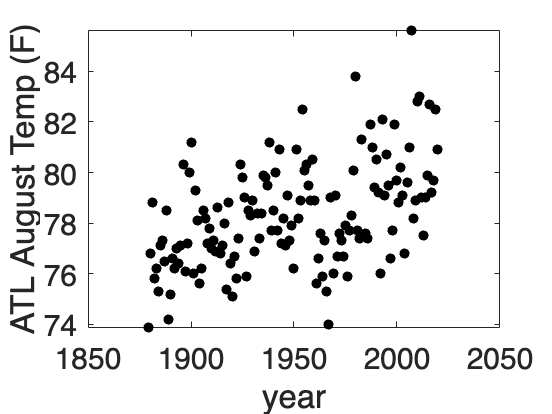

plot(year,augtemp,'k.','markersize',20)
ylabel('ATL August Temp (F)','fontsize',20)
xlabel('year','fontsize',20)
set(gca,'fontsize',20)

Now set up a matrix for a linear system with year as the explanatory variable

A = zeros(length(year),2);
A(:,1) = year;
A(:,2) = 1

A =         1879           1
        1880           1
        1881           1
        1882           1
        1883           1
        1884           1
        1885           1
        1886           1
        1887           1
        1888           1


Then calculate least squares solution using pseudoinverse

linfit = A\augtemp

linfit =     0.0239
   31.6934


First element of output is the slope of the line - or the trend in temperature (deg F) per year (.02 F/yr or 0.2 F/decade)

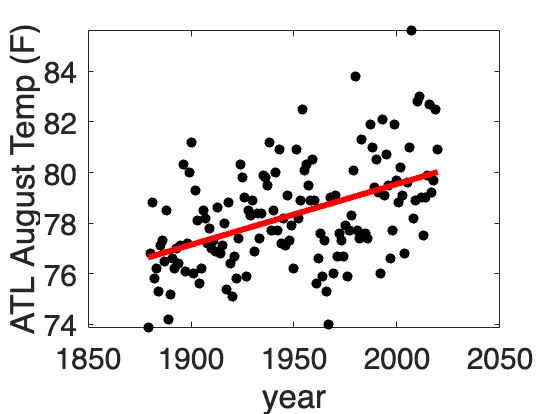

plot(year,augtemp,'k.','markersize',20);hold on
plot(year,linfit(2)+linfit(1).*year,'r-','linewidth',4)
ylabel('ATL August Temp (F)','fontsize',20)
xlabel('year','fontsize',20)
set(gca,'fontsize',20)